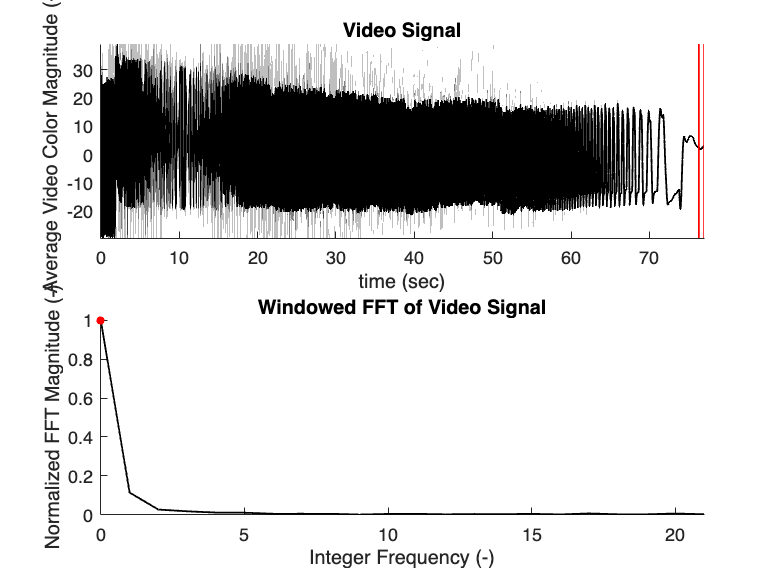

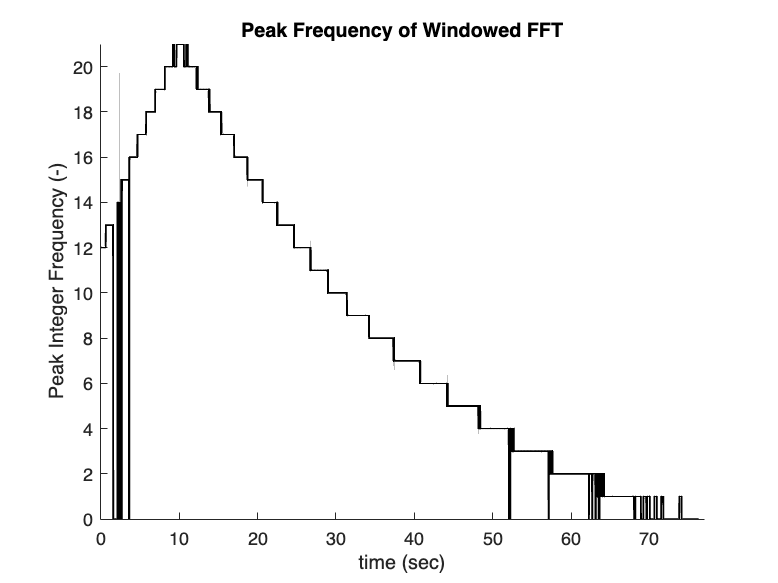

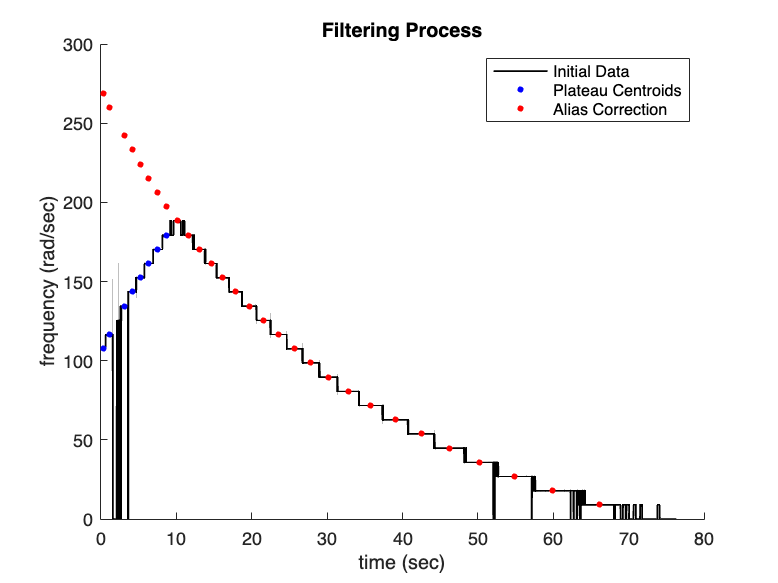

%T_window: width of FFT window (in seconds) .7 is usually good
T_window = .7;
%q: a parameter used to filter which portions of frequency curve to use
% (filter is by width of flat portions of curve)
% value should be in interval [0,1]
% values closer to 1 are most "exclusive".
% .6 is a pretty good value to choose
q = .6;
%showAnalysis: boolean that turns visualization on/off
showAnalysis = 1;
%uses FFT and some filtering tricks to extract angular velocity of fidget
%spinner as a function of time
%OUTPUTS:
%tlist: list of times for measured values of angular frequency
%omega_list: measured value of angular frequency
[tlist,freq_list] = fidget_spinner_FFT(y,Fs,T_window,q,showAnalysis);

% wTrue = wApparent/nWings
% true angular velocity = apparent / 3 wings
wTrue = freq_list / 3

wTrue =    89.6665   86.6776   80.6999   77.7110   74.7221   71.7332   68.7443   65.7555   62.7666   59.7777   56.7888   53.7999   50.8110   47.8221   44.8333   41.8444   38.8555   35.8666   32.8777   29.8888   26.9000   23.9111   20.9222   17.9333   14.9444   11.9555    8.9667    5.9778    2.9889
